clc; clear all; close all;

pyenv('Version', '/opt/anaconda3/bin/python');
run eidors-v3.11/eidors/startup.m;

EIDORS:[=== SETTING UP EIDORS version 3.11 ===]
EIDORS:[tested function eidors_var_id: OK]
 EIDORS:[Setting Default Colours]
EIDORS:[Installed EIDORS (Ver: 3.11)]
EIDORS:[Parameter: cache_size=1024 MB]
EIDORS:[Parameter: mapped_colour=127]
EIDORS:[Default background colour: white]
EIDORS:[EIDORS mex folder: /Users/piotrblaszyk/Documents/university/MRIGI/group-project-70006/EIDORS_FEM/eidors-v3.11/eidors/arch/matlab]
EIDORS:[EIDORS cache folder: /Users/piotrblaszyk/Documents/university/MRIGI/group-project-70006/EIDORS_FEM/eidors-v3.11/eidors/models/cache (must be writable)]
EIDORS:[EIDORS model cache: /Users/piotrblaszyk/Documents/university/MRIGI/group-project-70006/EIDORS_FEM/eidors-v3.11/eidors/models/cache]
EIDORS:[New to EIDORS? Have a look at the <a href="http://eidors3d.sf.net/tutorial/tutorial.shtml">Tutorials</a>.]


eidors_cache('clear_all');

## Load node positions, tetrahedra and electrode node labels

load('electrode_node_labels.mat');
num_electrodes = size(electrode_node_labels, 2);
middle_ix = ceil(num_electrodes / 2);
mid_electrode_label = electrode_node_labels(middle_ix);

data = load('mesh.mat');
node_positions_all = data.node_positions_all;
tetrahedra = data.tetrahedra;
ground_node_label = data.ground_node_label;

num_timesteps = size(node_positions_all, 1);

num_electrode_pairs = 10;
measurements_all = zeros(num_timesteps, num_electrode_pairs);

## Run EIDORS simulation for each Abaqus analysis timestep

1 

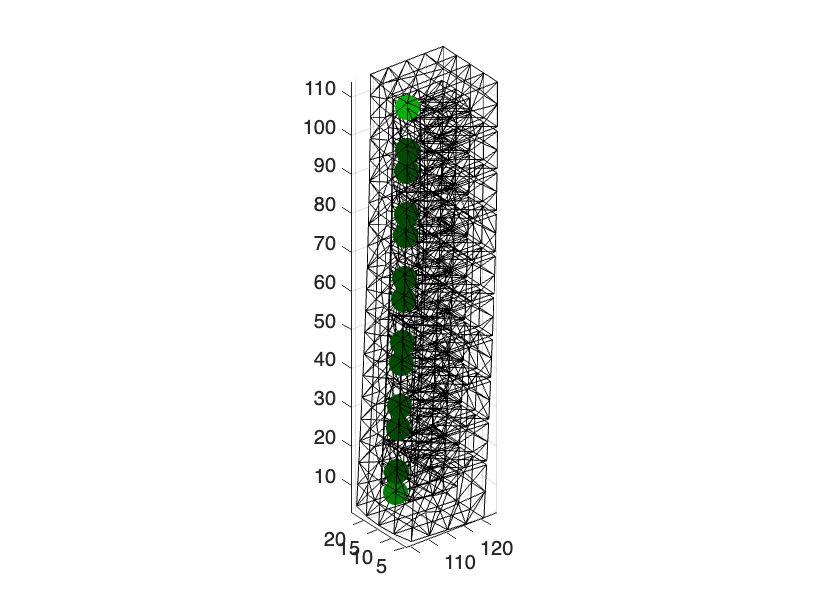

2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218 219 220 221 222 223 224 225 226 227 228 229 230 231 232 233 234 235 236 237 238 239 240 241 242 243 244 245 246 247 248 249 250 251 252 253 254 255 256 257 258 259 260 261 262 263 264 265 266 267 268 269 270 271 272 273 274 275 276 277 27

for i = 1:num_timesteps
    fprintf("%d ", i);
    node_positions = squeeze(node_positions_all(i, :, :));
    MDL = eidors_obj('fwd_model' , 'soft_actuator');
    MDL.nodes = node_positions;
    MDL.elems = tetrahedra;
    [srf idx] = find_boundary(tetrahedra);
    MDL.boundary = srf;
    MDL.gnd_node = ground_node_label;
    z_contact = 0.0000001;
    for j = 1:num_electrodes
        elecs(j).nodes = electrode_node_labels(j);
        elecs(j).z_contact = z_contact;
    end
    MDL.electrode = elecs;
    if i == 1 || i == num_timesteps
        figure;
        show_fem(MDL);
    end
    MDL = remove_unused_nodes(MDL);
    MDL.solve = @fwd_solve_1st_order;
    MDL.jacobian = @jacobian_adjoint;
    MDL.system_mat = @system_mat_1st_order;
    MDL.normalize_measurements = 0;
    Amp = 1;
    prt_eliko = [
        6, 3, 5, 4;
        5, 2, 4, 3;
        4, 1, 3, 2;
        3, 8, 2, 1;
        2, 9, 1, 8;
        1, 10, 8, 9;
        8, 11, 9, 10;
        9, 12, 10, 11;
        10, 13, 11, 12;
        6, 1, 4, 3;
        1, 13, 9, 11;
        6, 13, 2, 9;
    ];
    prt_simulation = zeros(size(prt_eliko));
    for j = 1:size(prt_eliko, 1)
        for k = 1:size(prt_eliko, 2)
            x = prt_eliko(j, k);
            if 1 <= x && x <= 7
                x = 8 - x;
            end
            prt_simulation(j, k) = x;
        end
    end
    prt_used_ix_list = [1, 3, 4, 5, 6, 7, 8, 9, 11, 12];
    prt_simulation_used = prt_simulation(prt_used_ix_list, :);

    stim = stim_meas_list(prt_simulation_used, num_electrodes, Amp);
    MDL.stimulation = stim;
    if ~valid_fwd_model(MDL)
        error("Invalid forward model");
    end
    S = 1.6;
    img = mk_image(MDL,S);
    img.fwd_solve.get_all_meas = 1;
    foo = fwd_solve(img);
    res = foo.meas;
    res = res';
    measurements_all(i, :) = res;
end


save('measurement.mat', 'measurements_all');